warning('off','all')

Do quizu:

Nmax = 10000;
eps = 0.05;
start = -0.7086;
stop = 0.2406;
[x, i] = gold_divide(start, stop, @g, eps, 10000);
x

x = -0.1056

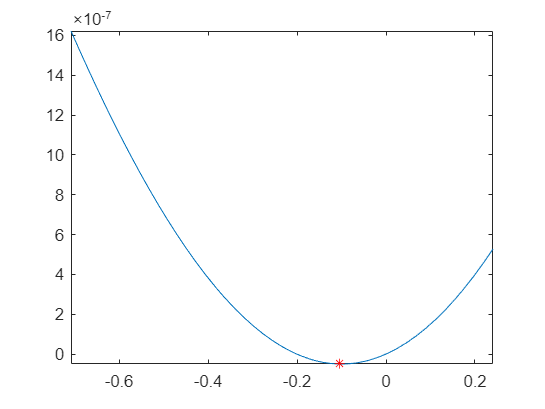

Dla funkcji g: 
Dla punktu startowego: -0.7086 i punktu końcowego: 0.2406
dokładności rozwiązania: 0.05
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -0.1056

Wynik otrzymano w 7 iteracjach


display('g', start, stop, eps, Nmax, x, i)

Do prezentacji:

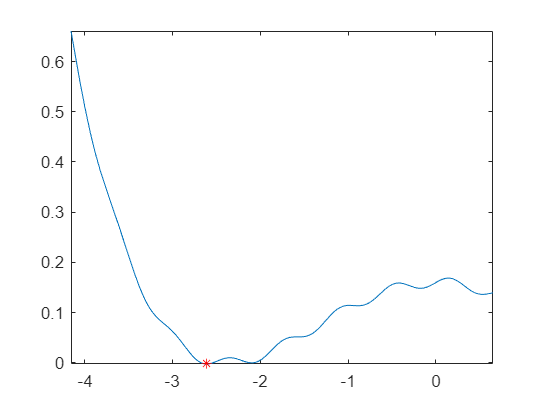

Dla funkcji f: 
Dla punktu startowego: -4.1557 i punktu końcowego: 0.64976
dokładności rozwiązania: 0.05
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -2.6075

Wynik otrzymano w 10 iteracjach


%Dla funkcji f(x) dla punktów startowych: -8, -0.5, 1, 8 z metody ekspansji:
start = [-4.1557, -3.0629, 1.7594, -0.64976];
stop = [0.64976, -1.6391, 2.7086, 4.1557];
%Dla funkcji g(x) dla punktów startowych: -8, -0.5, 1, 8 z metody ekspansji:
start1 = [-5.4371, -0.275, -0.70895, 20.9746];
stop1 = [-2.2335, 0.00625, 0.24062, 37.1929];

%Obliczamy minimum funkcji f(x) za pomocą metody złotego podziału dla wcześniej
%obliczonych punktów początkowych i końcowcych o dokładności eps = 0.05
[x, i] = gold_divide(start(1), stop(1), @f, 0.05, 10000);
display('f', start(1), stop(1), 0.05, Nmax, x, i)

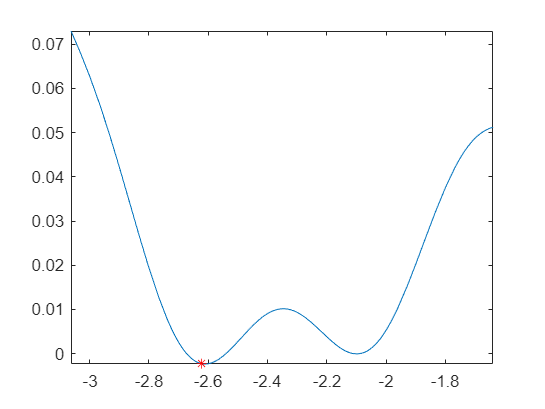

Dla funkcji f: 
Dla punktu startowego: -3.0629 i punktu końcowego: -1.6391
dokładności rozwiązania: 0.05
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -2.6229

Wynik otrzymano w 7 iteracjach



[x, i] = gold_divide(start(2), stop(2), @f, 0.05, 10000);
display('f', start(2), stop(2), 0.05, Nmax, x, i)

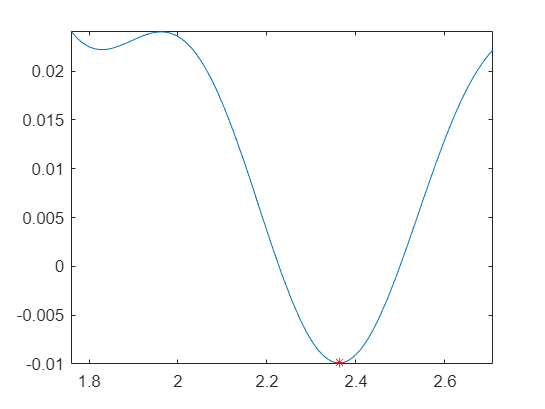

Dla funkcji f: 
Dla punktu startowego: 1.7594 i punktu końcowego: 2.7086
dokładności rozwiązania: 0.05
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
    2.3624

Wynik otrzymano w 7 iteracjach



[x, i] = gold_divide(start(3), stop(3), @f, 0.05, 10000);
display('f', start(3), stop(3), 0.05, Nmax, x, i)

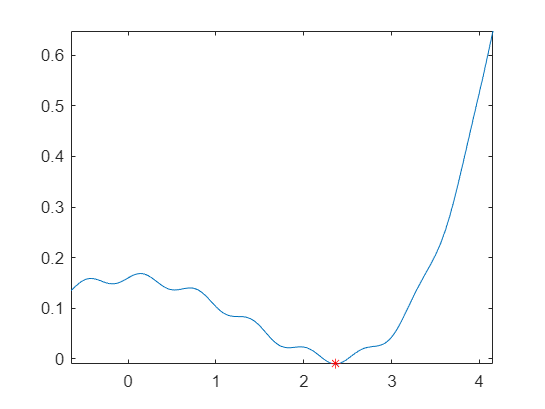

Dla funkcji f: 
Dla punktu startowego: -0.64976 i punktu końcowego: 4.1557
dokładności rozwiązania: 0.05
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
    2.3639

Wynik otrzymano w 10 iteracjach



[x, i] = gold_divide(start(4), stop(4), @f, 0.05, 10000);
display('f', start(4), stop(4), 0.05, Nmax, x, i)

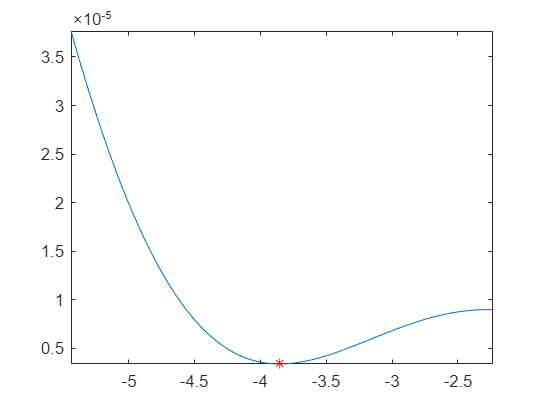

Dla funkcji g: 
Dla punktu startowego: -5.4371 i punktu końcowego: -2.2335
dokładności rozwiązania: 0.001
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -3.8536

Wynik otrzymano w 17 iteracjach



%Obliczamy minimum funkcji g(x) za pomocą metody złotego podziału dla wcześniej
%obliczonych punktów początkowych i końcowcych o dokładności eps = 0.001
[x, i] = gold_divide(start1(1), stop1(1), @g, 0.001, 10000);
display('g', start1(1), stop1(1), 0.001, Nmax, x, i)

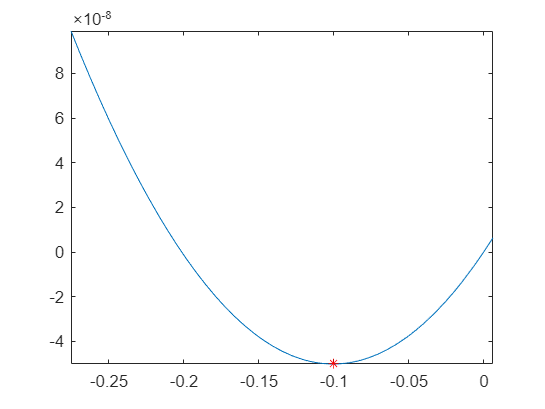

Dla funkcji g: 
Dla punktu startowego: -0.275 i punktu końcowego: 0.00625
dokładności rozwiązania: 0.001
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -0.1002

Wynik otrzymano w 12 iteracjach



[x, i] = gold_divide(start1(2), stop1(2), @g, 0.001, 10000);
display('g', start1(2), stop1(2), 0.001, Nmax, x, i)

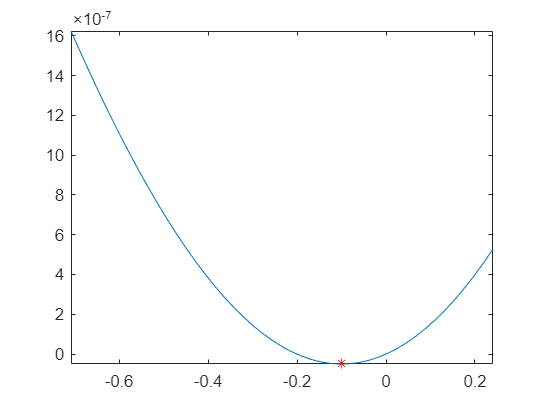

Dla funkcji g: 
Dla punktu startowego: -0.70895 i punktu końcowego: 0.24062
dokładności rozwiązania: 0.001
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   -0.1004

Wynik otrzymano w 15 iteracjach



[x, i] = gold_divide(start1(3), stop1(3), @g, 0.001, 10000);
display('g', start1(3), stop1(3), 0.001, Nmax, x, i)

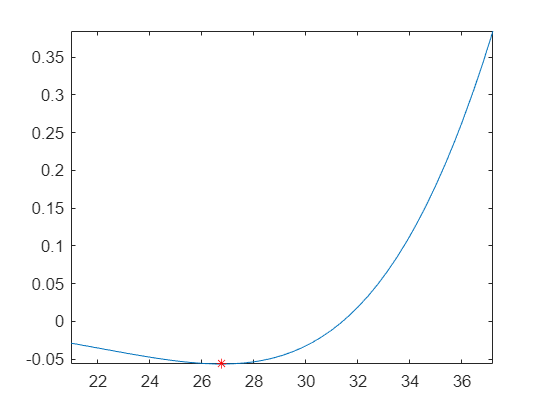

Dla funkcji g: 
Dla punktu startowego: 20.9746 i punktu końcowego: 37.1929
dokładności rozwiązania: 0.001
maksymalnej ilości liczby iteracji: 10000
minimum funkcji wyznaczone metodą złotego podziału to :
   26.7606

Wynik otrzymano w 21 iteracjach



[x, i] = gold_divide(start1(4), stop1(4), @g, 0.001, 10000);
display('g', start1(4), stop1(4), 0.001, Nmax, x, i)

Funkcja display do wyświetlania wyników:

function display(f, a, b, epsilon, Nmax, result, i)
    disp('Dla funkcji ' + string(f) +': ')
    disp(['Dla punktu startowego: ', num2str(a), ' i punktu końcowego: ', num2str(b)])
    disp(['dokładności rozwiązania: ', num2str(epsilon)]);
    disp(['maksymalnej ilości liczby iteracji: ', num2str(Nmax)])
    disp(['minimum funkcji wyznaczone metodą złotego podziału to :'])
    disp([(result)])
    disp(['Wynik otrzymano w ', num2str(i), ' iteracjach'])
    hold off
end

Funkcja f:

function f=f(x)
    f=0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2;
end

Funkcja g:

function g=g(x)
    px = [-10 -5 0 5 10];
    py = [0.0001 -0.1 0 0.1 -0.0001];
    stopien = 5;
    W = polyfit(px, py, stopien);
    g = (0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x;
end

Funkcja y:

function y = y(x)
   y = x + (1/x^2);
end

Funkcja gold_divide:

function [x, i] = gold_divide(start, stop, func, eps, Nmax)
    i = 0;
    alpha = (sqrt(5) - 1) / 2;
    a_i = start;
    b_i = stop;
    c_i = stop - alpha * (stop - start);
    d_i = start + alpha * (stop - start);
    
    while abs(b_i - a_i) > eps && i < Nmax
        if func(c_i) < func(d_i)
            a_i = a_i;
            b_i = d_i;
            d_i = c_i;
            c_i = b_i - alpha * (b_i - a_i);
        
        else
            a_i = c_i;
            b_i = b_i;
            c_i = d_i;
            d_i = a_i + alpha*(b_i - a_i);
        end
        i = i + 1;
        if i > Nmax
            fprinf("Nie udało znaleźć się rozwiązania w %d krokach", Nmax)
        end
        x = (a_i + b_i)/2;
    end
    figure()
    fplot(func,[start stop])
    hold on
    plot( x, func(x),'r*')
    hold off
    return;
end